 依赖[统一实验分析作图v18.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Non-similar RSPd activity

GroupNtats=TransferLearning.QueryNTATS('声光迁移RSPd');
Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);

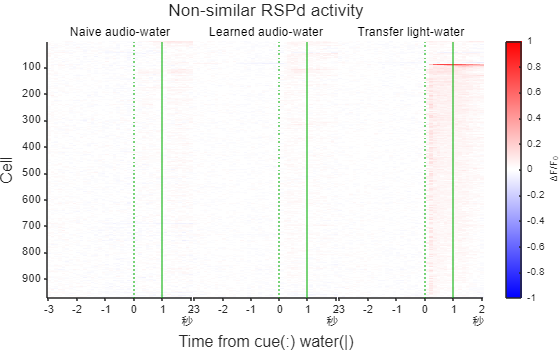

Data=GroupNtats.NTATS{:,:,["Naive","Learned","Transfer"]};
Data=Data(any(Data,2:3),:,:);
Layout=TransferLearning.AucGroupSortedHeatmap(Data,["Naive audio-water","Learned audio-water","Transfer light-water"],Colors,false,[-1,1]);
title(Layout,'Non-similar RSPd activity');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('RSPd迁移.svg'),'-dsvg');